clc; clear; close all;
disp("MATLAB Exercise: Homogeneous Transformation Matrix")

MATLAB Exercise: Homogeneous Transformation Matrix


%% Part a: Compute rotation matrix using Z-Y-X Euler angles
% Input example Euler angles α (alpha), β (beta), ɣ (gamma)and
% Position_vector
alpha = input('Input α (degree): '); 
beta = input('Input β (degree): '); 
gamma = input('Input ɣ (degree): ');
RelativePosition_Vector =input('Input RelativePosition_Vector(^A P_B):(e.g.  [1;0;1] ): ');

% Convert degrees to radians
alpha = deg2rad(alpha);
beta = deg2rad(beta);
gamma = deg2rad(gamma);

% Rotation matrices
Rz = [cos(alpha), -sin(alpha), 0;
      sin(alpha),  cos(alpha), 0;
      0,          0,          1];
Ry = [cos(beta),  0, sin(beta);
      0,          1, 0;
     -sin(beta),  0, cos(beta)];
Rx = [1, 0,         0;
      0, cos(gamma), -sin(gamma);
      0, sin(gamma), cos(gamma)];

% Combined Z-Y-X rotation matrix
R = Rz * Ry * Rx;
disp("Rotation Matrix (^A R_B):");

Rotation Matrix (^A R_B):


disp(R)

    0.9254    0.0180    0.3785
    0.1632    0.8826   -0.4410
   -0.3420    0.4698    0.8138



disp("Position_Vector (^A P_B):");

Position_Vector (^A P_B):


disp(RelativePosition_Vector)

     3
     0
     1




Homogeneous_Transformation_Matrix =[R,RelativePosition_Vector;0,0,0,1]

Homogeneous_Transformation_Matrix =     0.9254    0.0180    0.3785    3.0000
    0.1632    0.8826   -0.4410         0
   -0.3420    0.4698    0.8138    1.0000
         0         0         0    1.0000


AbsolutePosition_Vector=input('Input  AbsolutePosition Vector(^B P):(e.g. [1;0;1]) : ');
disp("AbsolutePosition_Vector (P_B):");

AbsolutePosition_Vector (P_B):


disp(AbsolutePosition_Vector)

     1
     0
     1



P_B=AbsolutePosition_Vector;

disp("Perform a homogeneous transformation(B2A)")

Perform a homogeneous transformation(B2A)


Ans_P=Homogeneous_Transformation_Matrix*[P_B;1];
disp('after trans,the ^A P is: ')

after trans,the ^A P is: 


P_A=[Ans_P(1);Ans_P(2);Ans_P(3)]

P_A =     4.3039
   -0.2778
    1.4718



% Plot original and rotated points
figure;
% plot3([RelativePosition_Vector(1), RelativePosition_Vector(1)+P_B(1)], [ RelativePosition_Vector(2),RelativePosition_Vector(2)+P_B(2)], [RelativePosition_Vector(3), RelativePosition_Vector(3)+P_B(3)], 'b-o', 'LineWidth', 2); hold on;
drawFrameAndPoint(RelativePosition_Vector,R,AbsolutePosition_Vector)

ans =   1×4 graphics 数组:

    Quiver    Quiver    Quiver    Line  


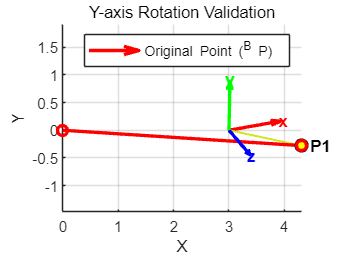

plot3([0, P_A(1)], [0, P_A(2)], [0, P_A(3)], 'r-o', 'LineWidth', 2);
%legend('Original Point (^B P)');
xlabel('X'); ylabel('Y'); zlabel('Z');
grid on;
title('Y-axis Rotation Validation');
axis equal;